**Modeling Scramjet Dynamics with ODE Solvers**

In my study of ordinary differential equations (ODEs), I explored MATLAB’s ODE solvers by modeling the dynamics of scramjet engines. Scramjets, or supersonic combustion ramjets, operate at extreme conditions where small tolerances in calculations can lead to vastly different results. This context provided an excellent opportunity to investigate the trade-offs between precision, tolerance settings, and computational efficiency using the `ode45` solver.

I modeled a simplified system where the combustion dynamics are described by an ODE. The system starts with an initial energy state, evolves over time, and incorporates effects such as energy dissipation and fluctuations in pressure. I defined the initial conditions and time span to represent the scramjet’s operational cycle during a supersonic flight.

To examine how tolerance impacts the results, I varied the relative (`RelTol`) and absolute (`AbsTol`) tolerances using `odeset`. Tighter tolerances aim to increase precision, but they also require more computational resources. I compared trajectories of the scramjet’s energy states under various tolerance settings, highlighting the differences caused by these adjustments.

To analyze the trade-offs between precision and computational efficiency, I timed the ODE solver with different tolerance levels. This revealed that while tighter tolerances provided slightly more precise solutions, they also significantly increased computation time. Such trade-offs are crucial in applications like scramjets, where both accuracy and real-time performance are critical.

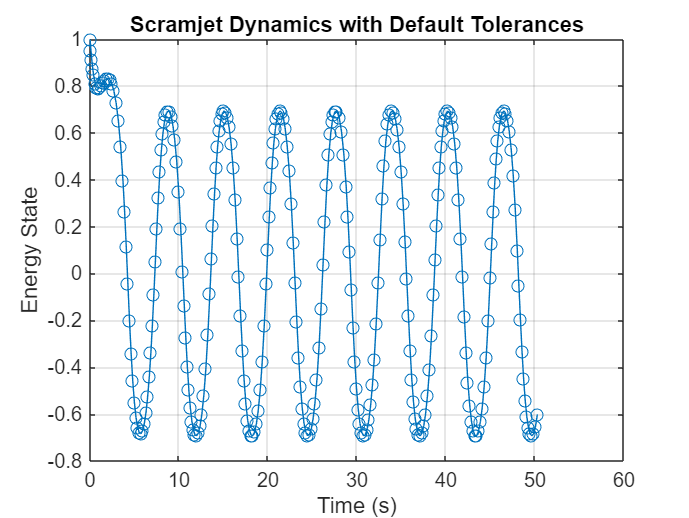

% Step 1: Define the ODE system
odefun = @(t, y) -0.5 * y + cos(y).^2 * sin(t); 
% I defined an ODE to represent the energy dynamics in a scramjet engine. 
% The term `-0.5 * y` models energy dissipation, while `cos(y).^2 * sin(t)` 
% adds oscillatory behavior to simulate fluctuations in combustion pressure over time.

% Step 2: Set the time span and initial conditions
tspan = [0, 16 * pi]; 
% I set the time span from 0 to 16π to simulate the scramjet’s performance over a complete operational cycle.

y0 = 1; 
% I initialized the energy state of the scramjet at 1 to represent a normalized starting condition.

% Step 3: Solve the ODE with default tolerances
[t, y] = ode45(odefun, tspan, y0); 
% I used the `ode45` solver with default settings as a baseline to observe how the solution evolves without any specific constraints.

figure; % I created a new figure to visualize the results.
plot(t, y, '-o'); 
% I plotted the solution to show how the energy state varies over time.
xlabel('Time (s)'); % I labeled the x-axis to represent time in seconds.
ylabel('Energy State'); % I labeled the y-axis to represent the normalized energy state.
title('Scramjet Dynamics with Default Tolerances'); 
% I added a title to describe the plot and highlight that this is the baseline case.
grid on; % I turned on the grid for better visualization of the trajectory.

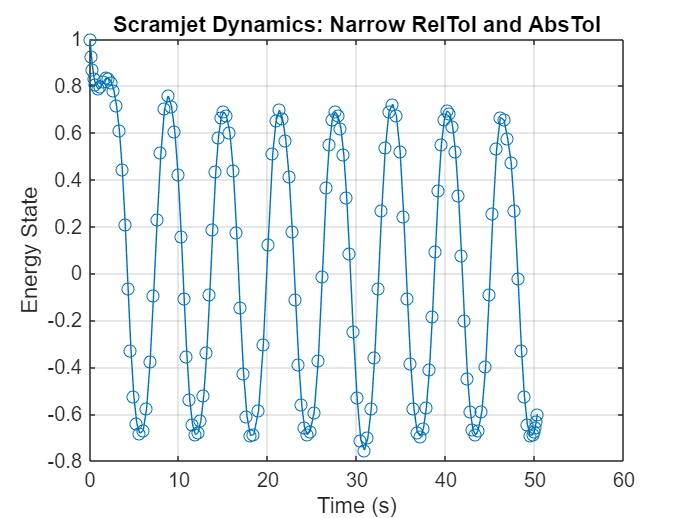


% Step 4: Solve the ODE with different tolerances to observe their effects
% Narrow relative and absolute tolerances
options1 = odeset('RelTol', 1e-2, 'AbsTol', 1e-2); 
% I chose a relative tolerance (`RelTol`) and absolute tolerance (`AbsTol`) of 1e-2 to observe how reduced precision affects the solution.

[t1, y1] = ode45(odefun, tspan, y0, options1); 
% I solved the ODE again using the specified tolerances.

figure; 
plot(t1, y1, '-o'); 
% I plotted the results to compare with the baseline solution.
xlabel('Time (s)'); 
ylabel('Energy State'); 
title('Scramjet Dynamics: Narrow RelTol and AbsTol'); 
grid on;

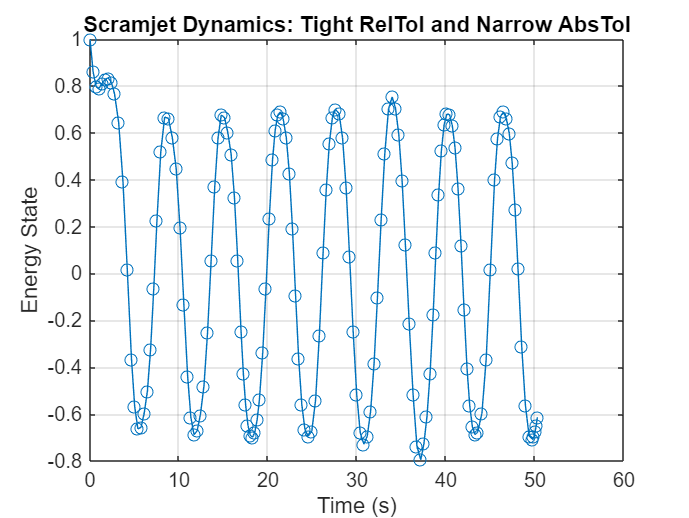


% Tight relative and narrow absolute tolerances
options2 = odeset('RelTol', 1e-7, 'AbsTol', 1e-2); 
% I tightened the relative tolerance to 1e-7 while keeping the absolute tolerance narrow (1e-2) 
% to examine the effect of prioritizing relative precision.

[t2, y2] = ode45(odefun, tspan, y0, options2); 
figure; 
plot(t2, y2, '-o'); 
xlabel('Time (s)'); 
ylabel('Energy State'); 
title('Scramjet Dynamics: Tight RelTol and Narrow AbsTol'); 
grid on;

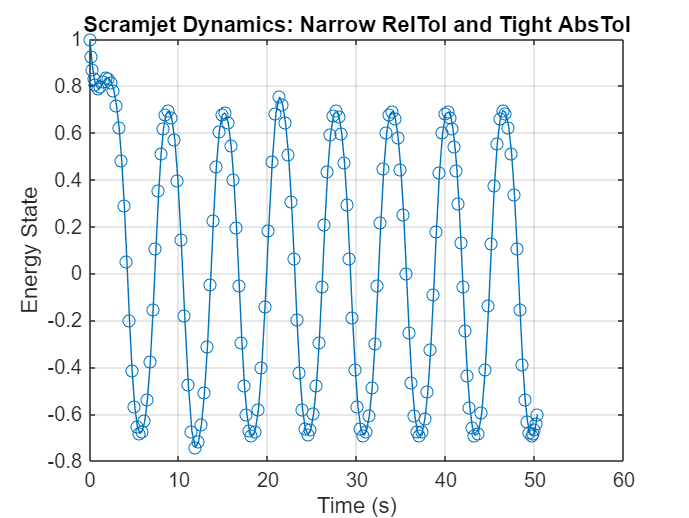


% Narrow relative and tight absolute tolerances
options3 = odeset('RelTol', 1e-2, 'AbsTol', 1e-7); 
% I swapped priorities, keeping the relative tolerance narrow (1e-2) but tightening the absolute tolerance (1e-7) 
% to explore the impact on accuracy.

[t3, y3] = ode45(odefun, tspan, y0, options3); 
figure; 
plot(t3, y3, '-o'); 
xlabel('Time (s)'); 
ylabel('Energy State'); 
title('Scramjet Dynamics: Narrow RelTol and Tight AbsTol'); 
grid on;

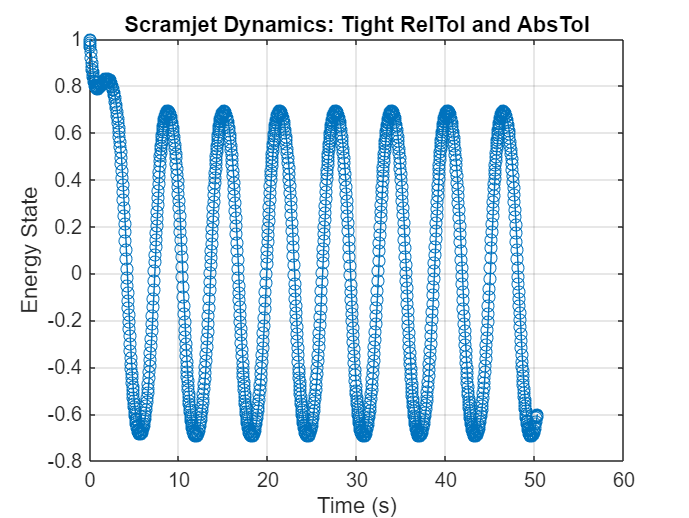


% Tight relative and absolute tolerances
options4 = odeset('RelTol', 1e-7, 'AbsTol', 1e-7); 
% I tightened both tolerances to 1e-7 to observe the most precise solution while considering computational cost.

[t4, y4] = ode45(odefun, tspan, y0, options4); 
figure; 
plot(t4, y4, '-o'); 
xlabel('Time (s)'); 
ylabel('Energy State'); 
title('Scramjet Dynamics: Tight RelTol and AbsTol'); 
grid on;


% Step 5: Analyze runtime trade-offs with varying tolerances
% Measure runtime for tight tolerances
tic; 
% I started the timer to measure how long the solver takes with tight tolerances.
options5 = odeset('RelTol', 1e-7, 'AbsTol', 1e-7); 
[t5, y5] = ode45(odefun, tspan, y0, options5); 
time1 = toc; 
% I stopped the timer and stored the runtime for comparison.

% Measure runtime for extremely tight tolerances
tic; 
options6 = odeset('RelTol', 1e-13, 'AbsTol', 1e-13); 
% I chose even tighter tolerances (1e-13) to evaluate the computational cost for higher precision.
[t6, y6] = ode45(odefun, tspan, y0, options6); 
time2 = toc; 

% Display runtime results
disp(['Runtime for RelTol=1e-7, AbsTol=1e-7: ', num2str(time1), ' seconds']); 

Runtime for RelTol=1e-7, AbsTol=1e-7: 0.026192 seconds


% I displayed the runtime for tolerances of 1e-7.
disp(['Runtime for RelTol=1e-13, AbsTol=1e-13: ', num2str(time2), ' seconds']); 

Runtime for RelTol=1e-13, AbsTol=1e-13: 0.075801 seconds


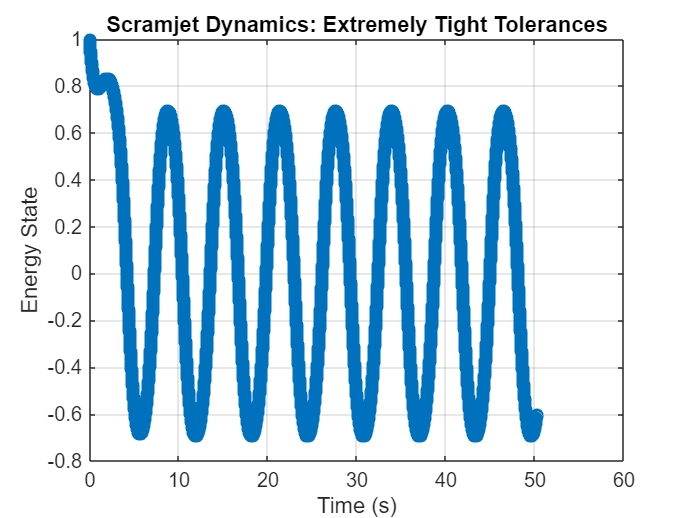

% I displayed the runtime for tolerances of 1e-13 to compare the cost of precision.

% Visualize results for extremely tight tolerances
figure; 
plot(t6, y6, '-o'); 
xlabel('Time (s)'); 
ylabel('Energy State'); 
title('Scramjet Dynamics: Extremely Tight Tolerances'); 
grid on; 

% I plotted the results for the most precise solution to observe any improvements in trajectory detail.

